clc
close all
clear all

T = readtable('s7055.dat');
data1 = table2array(T);
c = 0.265;
data = data1 * c;
L = length(data);

for i = 1:L-1
    dis(i) = abs(sqrt((data(i+1,1) - data(i,1)).^2 + ...
                      (data(i+1,2) - data(i,2)).^2));
    mid_data(i,:) = (data(i,:) + data(i+1,:)) * 0.5;
end

cg(1) = sum(transpose(mid_data(1:L-1,1)) .* dis) / sum(dis);
cg(2) = sum(transpose(mid_data(1:L-1,2)) .* dis) / sum(dis);

I_num = 0;
I_den = 0;

data(:,1) = data(:,1) - cg(1);
data(:,2) = data(:,2) - cg(2);

for i = 1:L-1
    I_num = I_num + (data(i,1) + data(i+1,1)) * ...
        (data(i,2) + data(i+1,2)) * 0.25 * dis(i);

    I_den = I_den + (data(i,2) + data(i+1,2)) * ...
        (data(i,2) + data(i+1,2)) * 0.25 * dis(i);
end

tan_alpha = I_num / I_den;

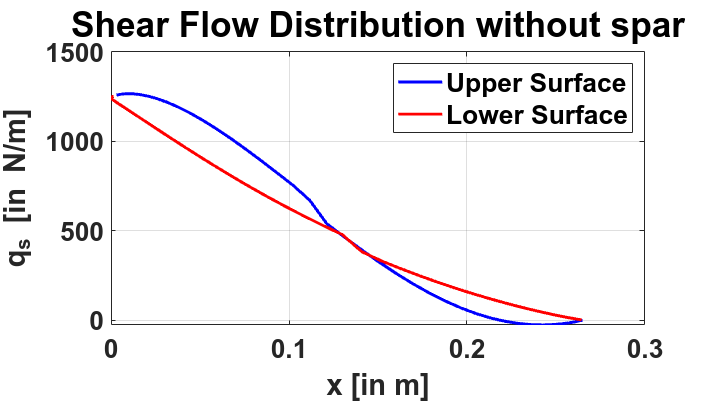

for i = 1:L-1
    p_d(i) = abs(data(i,2) - tan_alpha * data(i,1)) / ...
             sqrt(1 + tan_alpha^2);
end

a_boom(1:L-1) = 0;

for i = 1:L-1
    if i < L-1
        a_boom(i) = a_boom(i) + (1/6) * dis(i) * 0.0005 * ...
            (2 + (p_d(i+1) / p_d(i)));

        a_boom(i+1) = a_boom(i+1) + (1/6) * dis(i) * 0.0005 * ...
            (2 + (p_d(i) / p_d(i+1)));

    elseif i == L-1
        a_boom(i) = a_boom(i) + (1/6) * dis(i) * 0.0005 * ...
            (2 + (p_d(1) / p_d(i)));

        a_boom(1) = a_boom(1) + (1/6) * dis(i) * 0.0005 * ...
            (2 + (p_d(i) / p_d(1)));
    end
end

% Cut is made on the first panel
Vy = input('The shear force to be considered [in N] is: ');

data2 = transpose(data);
qs = find_shear(data2, a_boom, Vy, L);

figure('units','normalized','outerposition',[0 0 1 1])
plot(data2(1,1:0.5*(L-1)) + cg(1), ...
    -(qs(1:0.5*(L-1))), 'LineWidth',2,'Color','blue')
hold on
plot(data2(1,1+0.5*(L-1):L-1) + cg(1), ...
    -(qs(1+0.5*(L-1):L-1)), 'LineWidth',2,'Color','red')
grid on

set(gca,'FontSize',18,'FontName','Helvetica','FontWeight','bold')
xlabel('x [in m]')
ylabel('q_s [in N/m]')
legend('Upper Surface','Lower Surface','FontSize',18, ...
    'FontName','Helvetica','FontWeight','bold')
title('Shear Flow Distribution without spar','FontSize',24, ...
    'FontName','Helvetica','FontWeight','bold')

q0 = -sum(qs .* dis) / sum(dis); % Used line integral of q ds equal to zero
qs = qs + q0;
shear = qs;

a = input('The ribs spacing in m: ');

D = (pi*pi*70*(10^9)*(0.0005^3)*1.62) / ...
    (12*2.5*1.5*1.5*1.5*(1-0.33^2));

Kss = 5.34 + (4*0.234*0.234)/(a^2);
N = (Kss*D)/(0.234*0.234);

disp(max(abs(shear)))
disp(N)

if N > max(abs(shear))
    disp('No stringer needed without spar')
else
    disp('stringer needed without spar')
end

After comparing we are considering four booms

str_area = 10*0.001*0.001;
a_boom2 = a_boom;

iu = input('# stringers you want on upper surface: ');
iu_ind = input('iu stringers indices for 1 to 48 points: ');
% 49 at the end and 1 at first

il = input('# stringers you want on lower surface: ');
il_ind = input('il stringers indices for 1 to 48 points: ');

for i = 1:iu
    a_boom2(iu_ind(i+1)) = a_boom2(iu_ind(i+1)) + str_area;
end

for i = 1:il
    a_boom2(il_ind(i+1) + 0.5*(L+1)) = ...
        a_boom2(il_ind(i+1) + 0.5*(L+1)) + str_area;
end

qs2 = find_shear(data2,a_boom2,Vy,L);
q02 = -sum(qs2 .* dis) / sum(dis);

disp("Upper stringer location")

for i = 1:iu+1
    q_max2(i) = max(abs(qs2(iu_ind(i):iu_ind(i+1)-1) + q02));
    dis2(i) = sum(dis(iu_ind(i):iu_ind(i+1)-1));
    disp(data(iu_ind(i),1) + cg(1))
end

disp("Lower stringer location")

for i = 1:il+1
    q_max2(iu+1+i) = max(abs( ...
        qs2(0.5*(L-1)+il_ind(i): ...
        0.5*(L-1)+il_ind(i+1)-1) + q02));

    dis2(iu+1+i) = sum(dis(il_ind(i)+0.5*(L-1): ...
        il_ind(i+1)+0.5*(L-1)-1));

    disp(data(0.5*(L-1)+il_ind(i),1) + cg(1))
end

Kss2 = 5.34 + (4*(dis2.^2))/(a^2);
N2 = (Kss2*D)./(dis2.^2);

disp(N2 ./ q_max2)

figure('units','normalized','outerposition',[0 0 1 1])

plot(data2(1,1:0.5*(L-1)) + cg(1), ...
    -(qs2(1:0.5*(L-1))), 'LineWidth',2,'Color','blue')
hold on

plot(data2(1,1+0.5*(L-1):L-1) + cg(1), ...
    -(qs2(1+0.5*(L-1):L-1)), 'LineWidth',2,'Color','red')

grid on

set(gca,'FontSize',18,'FontName','Helvetica','FontWeight','bold')
xlabel('x [in m]')
ylabel('q_s [in N/m]')
legend('Upper Surface','Lower Surface','FontSize',18, ...
    'FontName','Helvetica','FontWeight','bold')
title('Shear Flow Distribution without spar with stringers', ...
    'FontSize',24,'FontName','Helvetica','FontWeight','bold')

figure('units','normalized','outerposition',[0 0 1 1])
hold on

for i = 1:iu+1
    plot(data(iu_ind(i):iu_ind(i+1),1) + cg(1), ...
        data(iu_ind(i):iu_ind(i+1),2) + cg(2), 'LineWidth',2)

    text(data(round(0.5*(iu_ind(i)+iu_ind(i+1))),1) + cg(1), ...
        data(round(0.5*(iu_ind(i)+iu_ind(i+1))),2) + cg(2) + 0.00234, ...
        sprintf('Panel %d',i),'FontSize',18,'FontWeight','bold')
end

il_ind = il_ind + 0.5*(L-1);

for i = 1:il+1
    plot(data(il_ind(i):il_ind(i+1),1) + cg(1), ...
        data(il_ind(i):il_ind(i+1),2) + cg(2), 'LineWidth',2)

    text(data(round(0.5*(il_ind(i)+il_ind(i+1))),1) + cg(1), ...
        data(round(0.5*(il_ind(i)+il_ind(i+1))),2) + cg(2) + 0.00234, ...
        sprintf('Panel %d',iu+1+i),'FontSize',18,'FontWeight','bold')
end

set(gca,'FontSize',18,'FontName','Helvetica','FontWeight','bold')
axis equal
grid on

xlim([min(data(:,1)+cg(1))-0.01 max(data(:,1)+cg(1))+0.01])
ylim([min(data(:,2)+cg(2))-0.011 max(data(:,2)+cg(2))+0.011])

xticks(min(data(:,1)+cg(1)):(0.1*c):max(data(:,1)+cg(1)))
yticks(round(linspace(min(data(:,2)+cg(2)), ...
    max(data(:,2)+cg(2)),7),4))

xlabel('x [m]')
ylabel('y [m]')
title('Section 3 with Stringers','FontSize',24, ...
    'FontName','Helvetica','FontWeight','bold')

figure('units','normalized','outerposition',[0 0 1 1])

plot(data(:,1)+cg(1),data(:,2)+cg(2), ...
    'LineWidth',2,'Color','blue')
hold on

scatter(data(:,1)+cg(1),data(:,2)+cg(2),50,'o', ...
    'MarkerFaceColor','red')

set(gca,'FontSize',18,'FontName','Helvetica','FontWeight','bold')
axis equal
grid on

xlim([min(data(:,1)+cg(1))-0.01 max(data(:,1)+cg(1))+0.01])
ylim([min(data(:,2)+cg(2))-0.011 max(data(:,2)+cg(2))+0.011])

xticks(min(data(:,1)+cg(1)):(0.1*c):max(data(:,1)+cg(1)))
yticks(round(linspace(min(data(:,2)+cg(2)), ...
    max(data(:,2)+cg(2)),7),4))

xlabel('x [m]')
ylabel('y [m]')
title('FX63137 Airfoil Idealised','FontSize',24, ...
    'FontName','Helvetica','FontWeight','bold')

% legend('Airfoil','Neutral Axis');

saveas(gca,'airfoil + booms.png')

function shear = find_shear(data2,a_boom2,Vy,L)

    cg_new(1) = sum(data2(1,1:L-1).*a_boom2) / sum(a_boom2);
    cg_new(2) = sum(data2(2,1:L-1).*a_boom2) / sum(a_boom2);

    data3(1,:) = data2(1,:) - cg_new(1);
    data3(2,:) = data2(2,:) - cg_new(2);

    Ixy2 = sum(data3(1,1:L-1).*data3(2,1:L-1).*a_boom2);
    Ix2 = sum((data3(2,1:L-1).^2).*a_boom2);
    Iy2 = sum((data3(1,1:L-1).^2).*a_boom2);

    den2 = Ix2*Iy2 - Ixy2^2;

    Kxy2 = Ixy2/den2;
    Kx2 = Ix2/den2;
    Ky2 = Iy2/den2;

    Qy2(1) = 0;
    Qx2(1) = 0;
    qs2(1:L-1) = 0;

    for i = 1:L-2
        Qy2(i+1) = Qy2(i) + data3(1,i+1)*a_boom2(i+1);
        Qx2(i+1) = Qx2(i) + data3(2,i+1)*a_boom2(i+1);

        qs2(i+1) = Vy*(Kxy2*Qy2(i+1) - Ky2*Qx2(i+1));
    end

    shear = qs2;
end